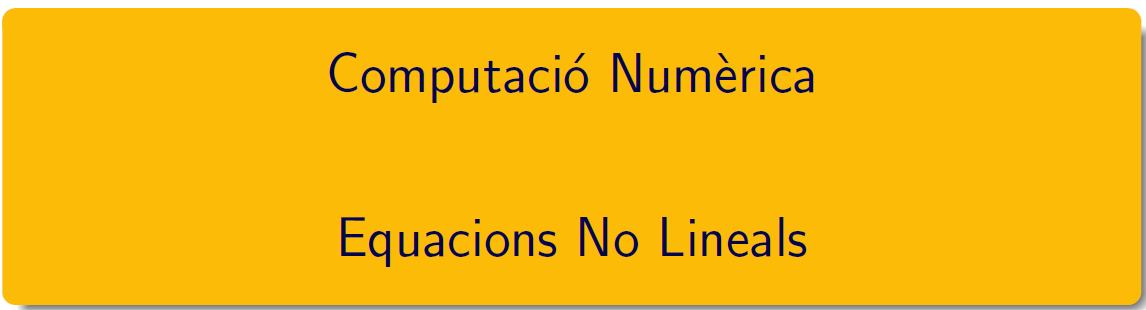

================================================================================

# Pràctica 7. Algorismes clàssics

`by M. Àngela Grau Gotés, març 2023`

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab7.pdf i en el document Exercicis_Tema4.pdf, els podeu trobar en el campus virtual. 

Consulteu els documents [Cleve Moler, Zeroin Algorithms](https://blogs.mathworks.com/cleve/2015/10/12/zeroin-part-1-dekkers-algorithm/)  i el capítol 4 de [Numerical Computing with MATLAB](https://es.mathworks.com/moler/chapters.html), Cleve Moler per a una primera versió dels algorismes de la pràctica.

## 1 Mètode de la bisecció

#### Funció test

- `Determinar l'arrel real del polinomi` $x^3-2x-5 =0$

Per als polinomis de grau tres sense terme quadratic, existeixen unes fòrmules de resolució directe: les fòrmules de Cardano. 

clear all
format longG
p = 2; 
q = 5;
s = sqrt(q^2/4 - p^3/27);
x0 = (q/2 + s)^(1/3) + (q/2 - s)^(1/3)

x0 =           2.09455148154233


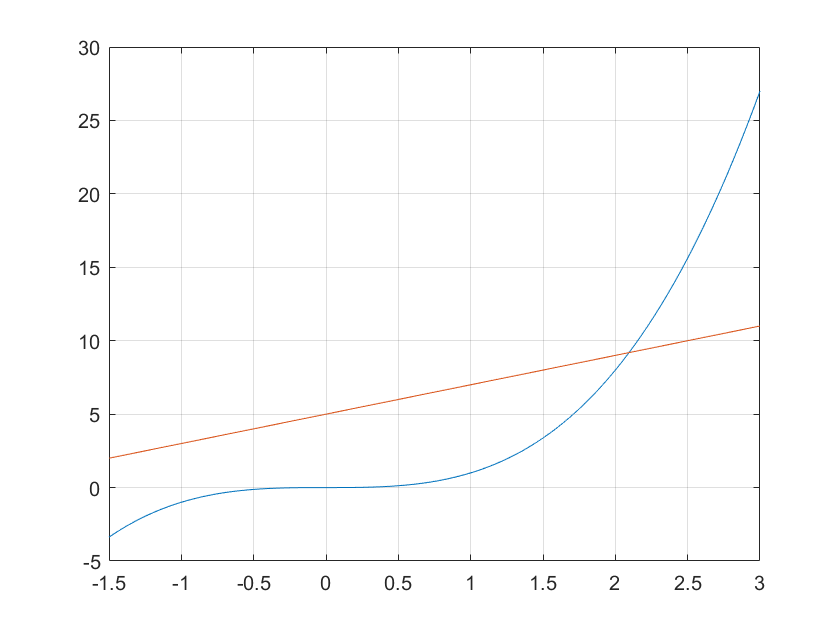

t = linspace(-1.5,3);
plot(t,t.^3,t,2*t+5),grid on

p = [1 0 -2 -5]; 
t=(1.4:0.2:2.4)';
ft = polyval(p,t);
disp(array2table([t,ft],"VariableNames",{'t','f(t)'}))

     t      f(t) 
    ___    ______

    1.4    -5.056
    1.6    -4.104
    1.8    -2.768
      2        -1
    2.2     1.248
    2.4     4.024



#### Pràctiquem.... Algorisme

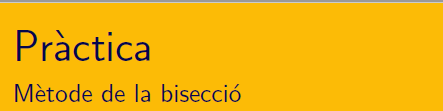

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la bisecció. Els arguments d'entrada han de ser l'interval inicial $$[a,b]$$i la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el punt mig $$\alpha_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

fun  = @(x) x^3 -2*x + 6

fun = function_handle with value:
    @(x)x^3-2*x+6


a = 10;
b = -10;
tol = 10e-8;
itmax = 50;
%function root = biseccio(a,b,tol,itmax,fun)
    it  = 0;
    fa = fun(a); fb = fun(b);
    
    while (it < itmax && abs(a-b) > tol)
        it = it +1;
        c = (a+b)/2;
        if (sign(fun(c)) == sign(fa))
            a = c;
        else 
            b = c;
        end
    end
%end
x = (a+b)/2, fun(x)   % yeyyyy

x =           -2.1799810603261


ans =       1.45024969810947e-07



%decimals correctes
dc = fix(-log10(2*abs(b-x)))

dc =      7


## 2 Mètode de la tangent

#### Funció test

- ` Calcular la solució ` `de l'equació `$e^x=\displaystyle 2-x$

#### Pràctiquem.... Algorisme

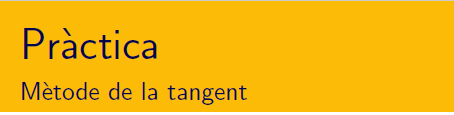

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la tangent. Els arguments d'entrada han de ser lel valor inicial $x_0$ i les funcions $$f$$i $f^\prime$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció per observar l'acompliment dels criteris d'aturada.

% buscar al llibre

## 3 Mètode de la secant

#### Funció test

- ` Calcular la solució pròxima a `$x_0=2$ `de l'equació `$\arctan(x)=\displaystyle\frac{2x}{x^2+1}$  

#### Pràctiquem.... Algorisme

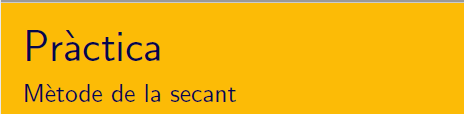

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la secant. Els arguments d'entrada han de ser els valors inicials $x_1$ i $x_2$ i  la funció $$f$$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció pels valors de la funció per observar l'acompliment dels criteris d'aturada.

## 4. Mètode de la iteració simple 

#### Funcions test

- Per a resoldre $x^3=2x+5$  es proposen els mètodes


$$
\mathbf{(f1)}~x_{n+1} = \frac12(x_n^3-5)\,,\qquad \mathbf{(f2)}~x_{n+1} = \sqrt[3]{2x_n+5}\,,$$
 

#### Pràctiquem.... Algorisme

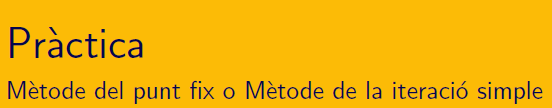

Escriure una funció de MATLAB® que trobi una solució de l'equació $$f(x)=0$$ pel mètode de la iteració simple. Els arguments d'entrada han de ser el valor inicials $x_1$, la funció $$f$$i la funció $g$. El valor de sortida $$\alpha$$, l'aproximació de l'arrel buscada. La funció ha d'escriure per pantalla una taula de resultats intermitjos: per cada iteració del métode ha de mostrar el valor calculat $$x_{n+1}$$ i els valors de la funció  per observar l'acompliment dels criteris d'aturada.

#### Pràctiquem.... Teorema de convergència

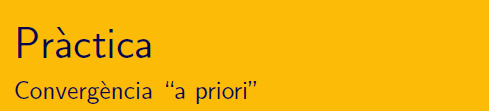

Escriure un `live script de MATLAB® `que:

- analitzi la convergència "a priori" del mètode de la iteració simple $x_{n+1} = g(x_n)$ consistent per a l'equació $f(x)=0$ i obtingui l'interval maximal de convergència en funció de la condició inicial $x_0$

- obtenir el nombre d'iteracions necessàries per acomplit el criteri d'aturada  $tol_x <\epsilon$